# Feedback Control Structures

A basic feedback loop as seen here is just that, basic. While it meets the basic requirements of feedback such as disturbance rejection, its ability to manage performance is limited due to the limited structure.

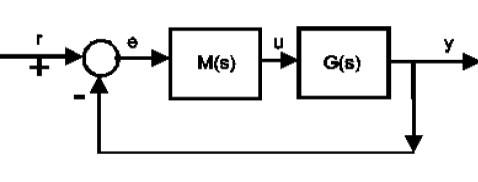

This file introduces some simple extensions of this which enable improvement of the properties such as tracking  and disturbance rejection. Using more available information as e.g. measurements of inner signals or disturbances and using these in control may improve the control performance.

We assume users are familiar with the basic analysis tools such as covered in ***plotting_with_matlab.mlx, *** ***transferfunctions_and_poles.mlx,*** ***step_responses_with_matlab.mlx and ***also with the*** effects_of_negative_feedback.mlx***

This live script needs the control toolbox.

### Similar files and the toolbox

See website below for more files like this.     [https://sites.google.com/sheffield.ac.uk/controleducation/matlabresources/section-6-11-community-control-toolbox](https://sites.google.com/sheffield.ac.uk/controleducation/matlabresources/section-6-11-community-control-toolbox)

This group of files can also be downloaded through MATLAB add-ons with the toolbox name:  **control101**

**For more information on those files uncomment and run either line of the code below:**

%  For documentation in a separate window type one of these 
%        Control101
%        doc Control101 Toolbox (pre 2024 only)
%        doc ("Control101 Toolbox")  
%        doc control101_toolbox. 
%  
%        help control101         (opens within the command window)

File written by Ruth Bars and László Keviczky,                        and J.A.Rossiter, University of Sheffield

Budapest University of Technology and Economics                                                 

                                 

## Table of contents

- Control in open- and in closed-loop

- Feedforward to reject output disturbances

- Cascade control

- Internal model control

## 1.Control in the open- and in closed-loop

The aim of a control system is to ensure reference signal tracking as well as disturbance rejection. Moreover, the control system should not be overly sensitive to measurement noises and to plant/model mismatch.

The control system should ensure several quality specifications (such as stability, static accuracy, properties of transient response, etc.). Also it has to be technically realisable, economical and satisfy miscellaneous other (e.g. environmental protection and safety) requirements. 

In the figure 1 below *G(s)* is the transfer function of the plant. Disturbances are assumed at both the output and the input of the plant. *M(s)* is the transfer function of the controller, * r*  denotes the reference signal and *y* is the output signal.

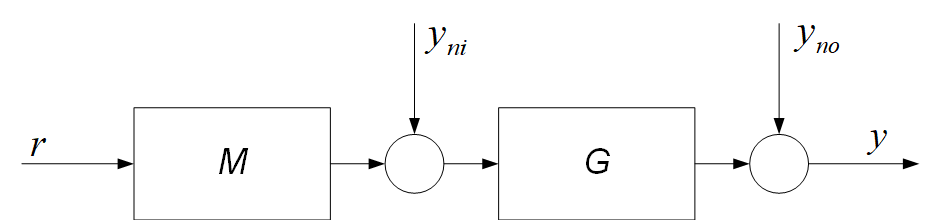

**Figure 1**: Forward path block diagram, open loop control

Reference signal tracking would be ideal if the controller could realise the inverse of the transfer function of the plant; generally this is not realisable and can only be approximated. In open loop in Figure 1, reference signal tracking may be reached  approximately, but the effect of the disturbances and other uncertainty cannot be eliminated. Therefore feedback is necessary as shown in the block diagram of Figure 2. 

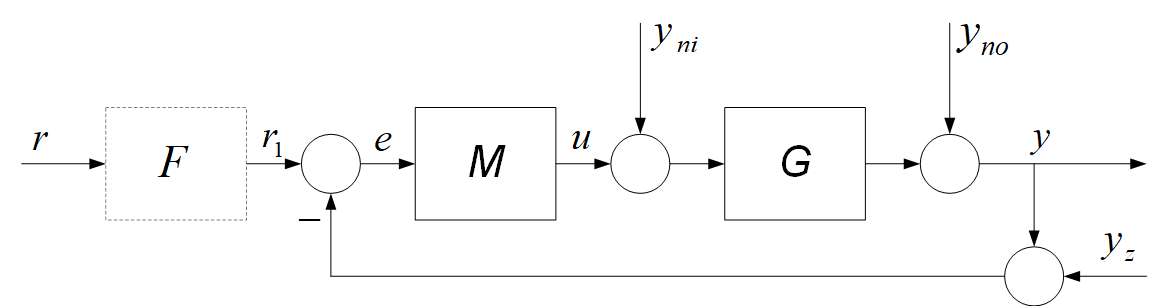

**Figure 2**: Feedback control structure 

Whatever effect (target changes, disturbance, uncertainty, ...) is causing the deviation of the output signal from its desired value, the error signal *e* will be different from zero creating a control signal which works to eliminate the deviation. Besides the input and output disturbances the measurement noise $y_{z\;}$ is also shown in the figure. Filter  *F*  modifies the reference signal and can improve tracking performance.

Some properties of the closed loop control system are discussed in file ***effects_of_negative_feedback.mlx.*** 

The closed loop control system has to track the reference signal and to decrease the effect of the input and output disturbances and also reject the effects of the measurement noise. The controller *M(s)* has to be designed to meet the quality specifications set for the static and dynamic behaviour of the control system. 

Design of controllers is discussed in files: ***proportional_design_with_bode.mlx, lag_design_with_bode.mlx, lead_design_with_bode.mlx, lead_lag_design_with_bode_toolbox.mlx, PID_Cont_Controller_Design_with_Pole_Cancellation.mlx, PID_tuning_methods_toolbox.mlx***

The behaviour of the control system can be improved if not only the output signal, but also some intermediate signals or the disturbances are measurable. Using more available information could improve the control performance. In the sequel some enhancements of the control system will be shown.

Summarising: Besides the usual control structure some extensions of feedback control are considered in the sections below where additional information of measurable disturbances or inner signals are used to improve the control performance.

## 2. Feedforward to reject output disturbances

If the disturbance is measurable, then the closed loop control is often supplemented by feedforward path using the measured value of the disturbance as shown in the block diagram in figure 3 below. The measured output disturbance acts on the output through the block represented by transfer function *Gn(s)*. The measured disturbance signal is fed forward through the block given by transfer function *Mn(s)* to the summation point at the input of the plant. In this way it is possible to execute control actions to reject much of the disturbance before its effect would appear in the controlled variable. With appropriate design of the feedforward controller, the effect of the disturbance can be significantly decreased.

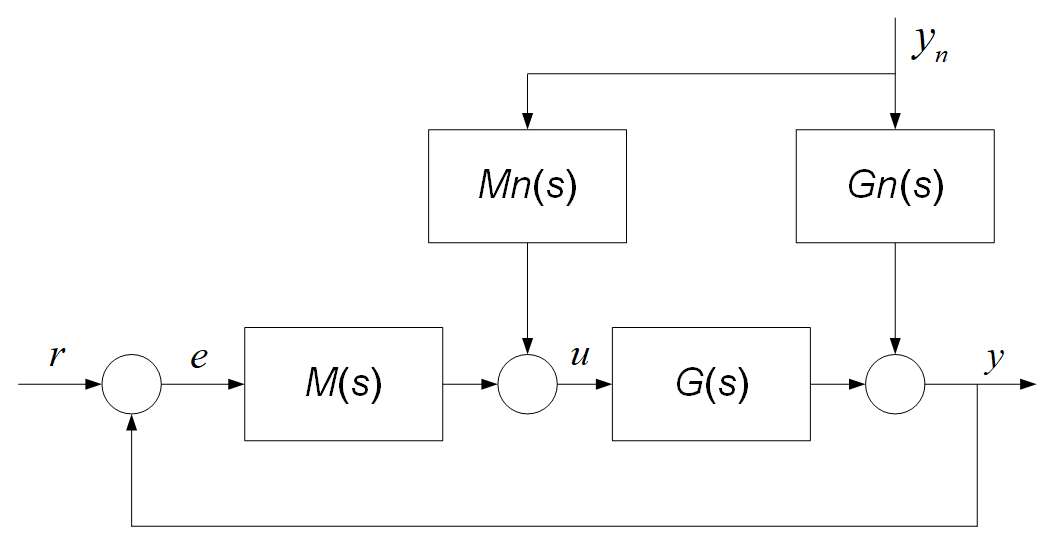

**Figure 3**: Feedback structure with feedforward information on output disturbances

The transfer function between the output and the disturbance is:


$$\frac{y\left(s\right)}{y_n \left(s\right)}=\frac{\textrm{Gn}\left(s\right)+\textrm{Mn}\left(s\right)G\left(s\right)}{1+M\left(s\right)G\left(s\right)}$$


**Remark**:  The effect of the disturbance on the output will be zero if  $\textrm{Gn}\left(s\right)+\textrm{Mn}\left(s\right)G\left(s\right)=0$, that is $\textrm{Mn}\left(s\right)=-\frac{\textrm{Gn}\left(s\right)}{G\left(s\right)}$ although such a design is unlikely to be implementable in general.

If this ideal transfer function is realisable (the degree of its numerator is not higher than the degree of its denominator, furthermore G(s) does not contain dead time), then the effect of the feedforward is perfect, the effect of the disturbance does not appear at all in the output signal. If *Mn*(s) is not realisable, it can be approximated by its best realisable approximation. As it sits outside the loop, *Mn*(s) does not effect stability.

### Case study

Consider the control scheme of a belt dryer furnace shown in the figure 4 below. 

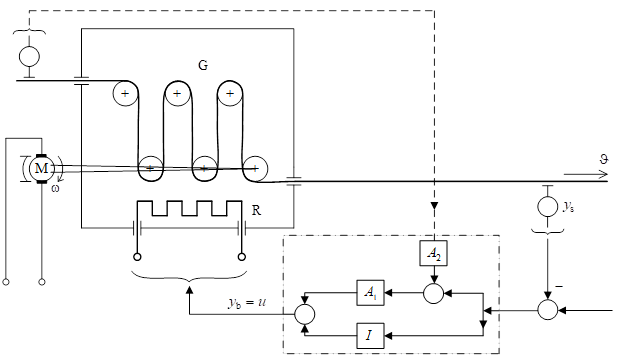

**Figure 4**: A belt dryer furnace

In the electrically heated furnace the material to be dried goes through the conveyor G driven by motor M. The controlled signal is the moisture content of the material leaving the furnace. At a given conveyor speed the material stays in the furnace for a given time. The manipulated variable is the heating power which can be changed by voltage u. The humidity of the material leaving the furnace is measured. It is compared to the reference signal. Deviations of the heating power are modified through a PI controller. The main disturbance source is the change of the humidity of the incoming material. Time is needed to eliminate the effect of the disturbance.The control system works against this only after that the effect of the disturbance has been measured at the output. Thus for a given time the humidity of the outcoming material will differ from its desired value. If the humidity of the incoming material is measurable, then this value can be used immediately, modifying the heating value through the feedforward part of the controller; the feedforward part of the controller is denoted by dashed line on figure 4.

As a numerical example consider a process modeled by a first order lag element with dead time, $G\left(s\right)=\frac{5}{1+10s}e^{-0\ldotp 1s}$. The output disturbance acts through the transfer element given by  $\textrm{Gn}\left(s\right)=\frac{2}{1+2s}$. The feedback controller is a PI controller, whose transfer function is $M\left(s\right)=\frac{1+10s}{s}$. The feedforward controller is given as $\textrm{Mn}\left(s\right)=\frac{-2s-0\ldotp 2}{s+0\ldotp 5}$, which is ideal if there is no dead time in the process. The code below demonstrates the behaviour of this feedback implementation.

disp('Section 2: Analysis of feedforward')

Section 2: Analysis of feedforward



disp('The process')

The process


G=tf(5,[10,1]);
G1 = tf(5,[10,1],'iodelay',0.1)

G1 =
 
                   5
  exp(-0.1*s) * --------
                10 s + 1
 
Continuous-time transfer function.
Model Properties


disp('The PI controller')

The PI controller


M=tf([10 1],[1 0]);
L=minreal(G1*M,0.001);
disp('Dynamics of output disturbance')

Dynamics of output disturbance


Gn=tf(2,[2 1]);
disp('The feedforward controller')

The feedforward controller


Mn=-Gn/G;
Mn=minreal(Mn,0.001)

Mn =
 
  -2 s - 0.2
  ----------
   s + 0.5
 
Continuous-time transfer function.
Model Properties


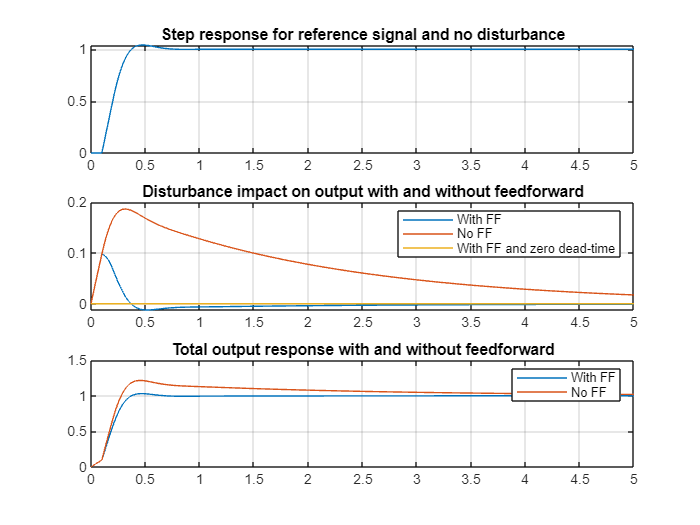


% Closed-loop relationships
T=feedback(L,1);    % target to output
TTo=(Gn)/(1+L); % disturbance to output with no feedforward
TTc=(Gn+Mn*G1)/(1+L); % disturbance to ouput with feedforward
TTT=(Gn+Mn*G)/(1+L); % disturbance to output assuming zero dead-time

% Closed-loop simulations
t=0:0.01:5;
y=step(T,t);
ydc=step(TTc,t);   % disturbance impact with FF
ydo=step(TTo,t);   % disturbance impact with no FF
yd3=step(TTT,t);   % disturbance impact with FF and no deadtime


subplot(311)
plot(t,y),grid
title('Step response for reference signal and no disturbance')

subplot(312)
plot(t,ydc,t,ydo,t,yd3),grid
title('Disturbance impact on output with and without feedforward')
legend('With FF','No FF','With FF and zero dead-time')

subplot(313)
plot(t,y+ydc,t,y+ydo),grid
title('Total output response with and without feedforward')
legend('With FF','No FF')

## 3. Cascade control

Typical processes can often be separated into serially connected parts, and besides the final output signal, some of the intermediate signals can also be measured. It would make sense then to exploit the information available in these intermediate measurements in order to improve overall behaviour. Such a concept leads to what is known as cascade control where separate control laws/loops exploit this information.

The block diagram of the process is shown on the figure 5 below. The disturbances may act directly on the output or between the two parts of the process. It is supposed that the disturbances themselves are not measurable.

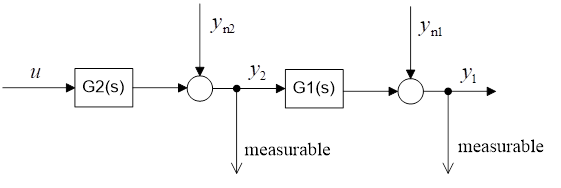

**Figure 5**: Process forward path with intermediate measurements

In a conventional control circuit the effect of the inner and of the outer disturbances should appear in the error signal, then the control system starts to operate in order to reject their effect. If the outer part of the process contains big time delays the control process will be slow. It is worthwhile to create an inner loop from the measurable $y_2$ signal which will reject the effect of the inner disturbance fast, and the outer loop will ensure good reference signal tracking and will reject the effect of the outer disturbance and also further attenuate the already decreased effect of the inner disturbance. This structure is the cascade control as shown in the figure 6 below. More than two cascade loops may also occur. The saturation block ensures limited reference value for the inner circuit. For fast behaviour of the inner circuit the M2 controller can be of P or PD type - no integral is required. The outer controller M1 ensures accurate reference signal tracking, so it can be of PI or PID type.

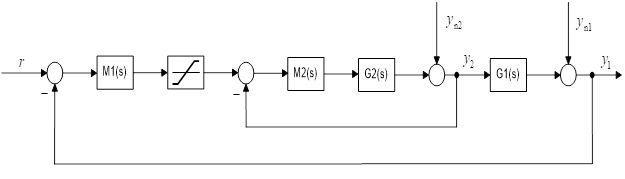

**Figure 6**: Basic cascade control structure

### Case study

Cascade control is applied generally in speed or position control of electrical drives where the output variable is the speed or the position and the internal variable is the current (see the schematic figure 7 below). It is important to keep the value of the armature current within the allowed limits.The current may reach very high values when starting,  breaking or loading the motor, while the speed is developed more slowly because of the mechanical inertia of the system. So not only the speed is measured and fed back but also an inner feedback is realised from the measured value of the current.

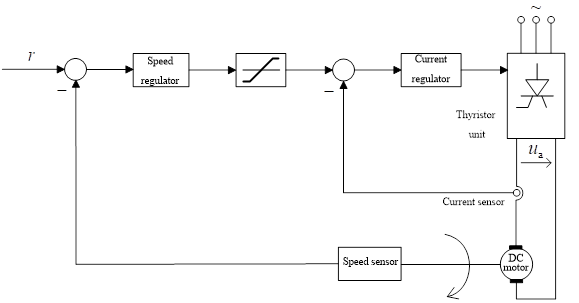

**Figure 7**: Cascade control structure for a DC motor

The code below illustrates the above scenario. Cascade loops are clumsy to code in MATLAB script so it makes more sense to represent these structures using simulink. Hence the a simulink model ***cascade_control101.slx*** of the cascade system developed and used in the code below to analyse the system behaviour. Disturbances are added mid-simulation.

disp('Section 3: Illustration of cascade control')

Section 3: Illustration of cascade control


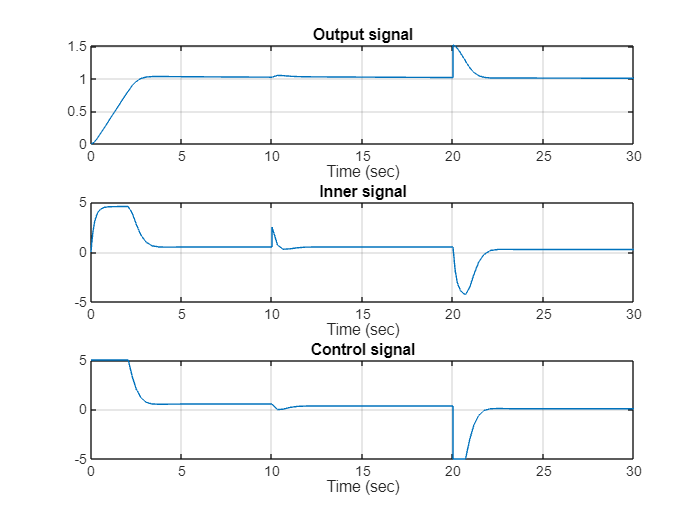


% Run the Simulink simulation with the cascade controller
% Consider the following subsystems and controllers
G1 = tf(2,[20 1]);
G2 = tf(5,[2 1]);
M1 = tf([20 1],[1 0]);
M2=tf(2,1);
endtime=30;

% Run the simulink model and extract the data
currentdisturbance=2; currentdisturbancetime = 10;
outputdisturbance = 0.5; outputdisturbancetime = 20;
Data=sim('cascade_control101.slx');
y1=Data.y1.signals.values;
y2=Data.y2.signals.values;
u=Data.u.signals.values;
t = Data.u.time;

% Plotting
subplot(311)
plot(t,y1),grid
xlabel('Time (sec)')
title('Output signal')
%
subplot(312)
plot(t,y2),grid
xlabel('Time (sec)')
title('Inner signal')
%
subplot(313)
plot(t,u),grid  
xlabel('Time (sec)')
title('Control signal')

Student tasks: 

- Run cascade control with other plants and other controllers.

- Compare the efficacy of the disturbance rejection with and without the inner loop.

Remark: Inner feedback of lag elements through constants will accelerate the behaviour of the system as shown in file ***effects_of_negative_feedback.mlx.***

Remark: State feedback can be considered as generalisation of cascade control. The output and the inner measured signal can be considered as state variables. If not only two (or some) state variables are measured and fed back through appropriate constants, but all the state variables (in an n-order system their number is n) then state feedback structure is realised. Details of state feedback control are discussed elsewhere, for example in files ***state_feedback_control101.mlx, State_feedback_and_state_estimation_cont_case_study.mlx***. 

## 4. Internal model control

Garcia and Morari have introduced the simple structure of internal control shown in the figure 8 below. This exploits a model of the process which is simulated in parallel with the process.

           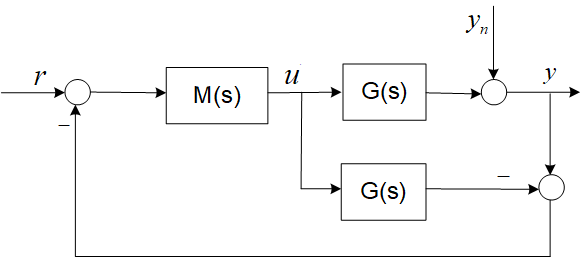

**Figure 8**: Internal model control structure 

First let us suppose that the transfer function *G(s)* of the process and its parallel connected model are identical and there is no disturbance $y_n$. Then the controller *M(s)* can be designed in open loop to ensure tracking of the r reference signal - this is because the right hand summing junction will have an output of zero in the ideal case and thus there is, in effect, no feedback. The best controller would be the inverse of the transfer function of the process. If this is not realisable then its best approximation should be considered.

The feedback loop becomes active if there is disturbance or if there is difference between the process and its model.

Let us build the internal model structure in simulink. Give the plant transfer function and also the transfer function of its model. Define the controller approximating the inverse of the transfer function of the plant. Any dead-time cannot be compensated. For the simulation we assume a mismatch between the plant and its model and a disturbance.

disp('Section 4: Internal model control')

Section 4: Internal model control


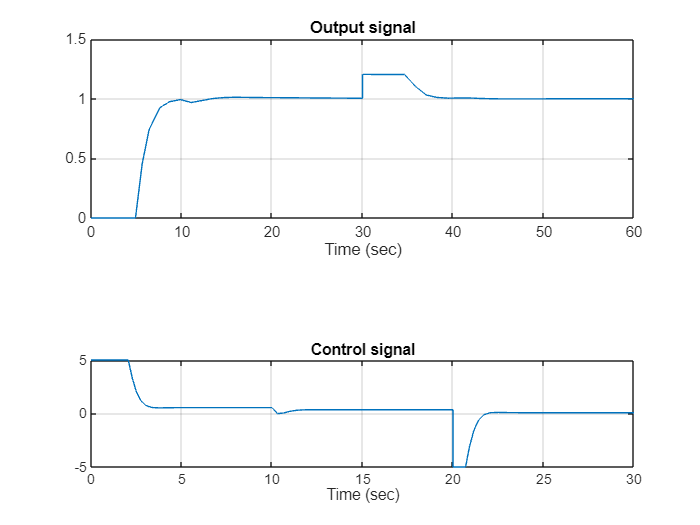


% Run the Simulink simulation with the internal model controller
% Consider the following system and the controller
G=tf(2,[10 1]);
Gm = tf(2,[9.8 1]);
M=tf(0.5*[10 1],[1 1]);
deadtime=5;
deadtimem=5.1;
endtime=60;

% Simulink simulation
Data=sim('internal_model_control101.slx');
y=Data.y.signals.values;
u=Data.u.signals.values;
t = Data.u.time;

% Plotting
subplot(211)
plot(t,y),grid
xlabel('Time (sec)')
title('Output signal')

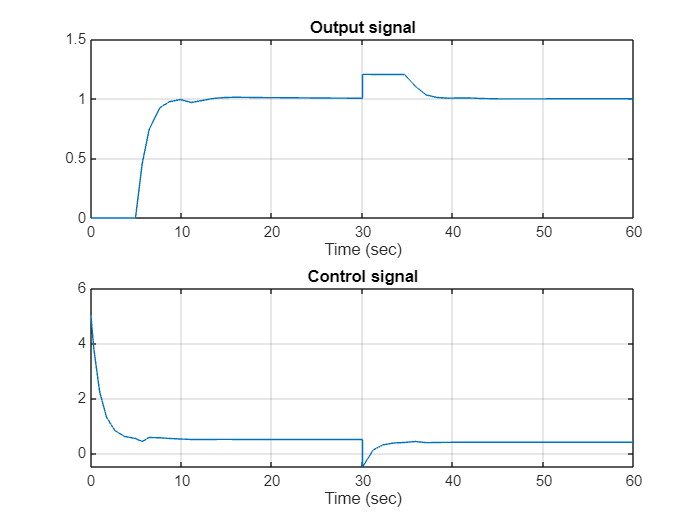


subplot(212)
plot(t,u),grid  
xlabel('Time (sec)')
title('Control signal')

Student tasks: 

- Run the internal model control with other differences between the plant and its model and even no mismatch. 

- Experiment with this control approach on other plants and other controllers supposing small plant/model mismatch values.

*Reference*: Garcia, C.E., Morari, M. Internal Model Control 1. A Unifying Approach and Some New Results. Industrial & Engineering Chemistry Process Design and Development, 21 (2), 308-323, 1982.